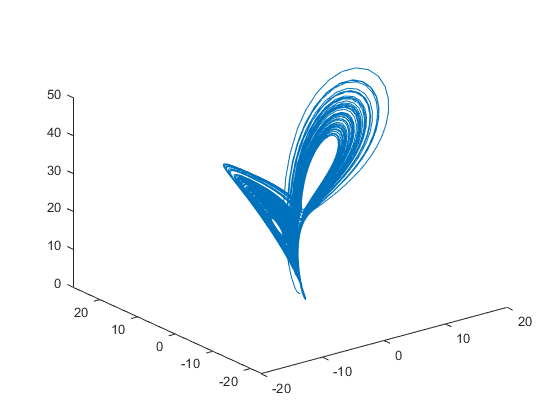

% Solve over time interval [0,100] with initial conditions [1,1,1]
% ''f'' is set of differential equations
% ''a'' is array containing x, y, and z variables
% ''t'' is time variable

% Lorenz 

sigma = 10;
beta = 8/3;
rho = 28;
f = @(t,a) [-sigma*a(1) + sigma*a(2); rho*a(1) - a(2) - a(1)*a(3); -beta*a(3) + a(1)*a(2)];
[t,a] = ode45(f,[0 100],[1 1 1]);     % Runge-Kutta 4th/5th order ODE solver
plot3(a(:,1),a(:,2),a(:,3))

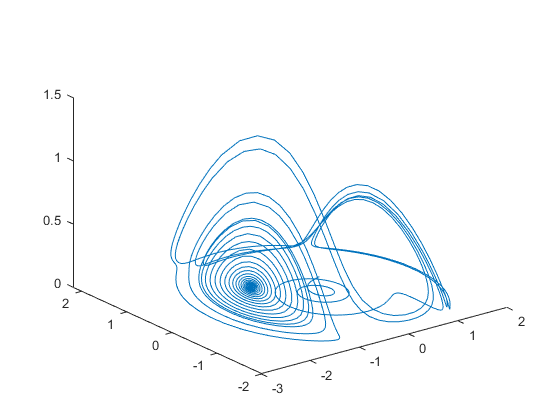


% 
% a(1) = x ; a(2) = y; a(3) = z
alfa = 0.2715;
gama = 0.1;
t_max = 500;

f = @(t,a) [a(2)*(a(3)-1+a(1)^2)+gama*a(1); a(1)*(3*a(3)+1-a(1)^2)+gama*a(2); -2*a(3)*(alfa+a(1)*a(2))];
[t,a] = ode45(f,[0 t_max],[0.1 0.1 0.1]);     % Runge-Kutta 4th/5th order ODE solver
plot3(a(:,1),a(:,2),a(:,3))



% XOY then z=0
z=0;
sys=@(t,x) [x(2)*(z-1+x(1)^2)+gama*x(1); x(1)*(3*z+1-x(1)^2)+gama*x(2); -2*z*(alfa+x(1)*x(2))];
figure(1)
vectorfield(sys,-20:2:20,-50:2:50);
hold on
sep=5;
for x0=-20:sep:20
for y0=-50:sep:50
[ts,xs] = ode45(sys,[0 t_max],[x0 y0 0]);
plot(xs(:,1),xs(:,2))
title('Vector field when z = 0');
xlabel('x');
ylabel('y');
end
end
axis([-20 20 -50 50]);
hold off

% XOZ then y=0
y=0;
sys=@(t,x) [y*(x(2)-1+x(1)^2)+gama*x(1); x(1)*(3*x(2)+1-x(1)^2)+gama*y; -2*x(2)*(alfa+x(1)*y)];
figure(1)
vectorfield(sys,-20:2:20,-50:2:50);
hold on
sep=5;
for x0=-20:sep:20
for z0=-50:sep:50
[ts,xs] = ode45(sys,[0 t_max],[x0 z0 0]);
plot(xs(:,1),xs(:,2))
title('Vector field when y = 0');
xlabel('x');
ylabel('z');
end
end
axis([-20 20 -50 50]);
hold off


% YOZ then x=0
xx=0;



sys=@(t,x) [x(1)*(x(2)-1+xx^2)+gama*xx; xx*(3*x(2)+1-xx^2)+gama*x(1); -2*x(2)*(alfa+xx*x(1))];
figure(1)
vectorfield(sys,-20:2:20,-50:2:50);
hold on
sep=5;
for y0=-20:sep:20
for z0=-50:sep:50
[ts,xs] = ode45(sys,[0 t_max],[y0 z0 0]);
plot(xs(:,1),xs(:,2))
title('Vector field when x = 0');
xlabel('y');
ylabel('z');
end
end
axis([-20 20 -50 50]);
hold off